clear all
load ARTEMIS.mat;
load ARTEMIS_road.mat
load WLTC.mat
start=0;%Definisci l'istante iniziale
N=5; %Time horizon
u=[];
%definisci le opzioni per l'optimisation
opts=optimoptions('fmincon','MaxFunctionEvaluations',1e3,...
    'Algorithm','sqp','ConstraintTolerance',1e-3,'Display','none');
    
ARTEMIS=ARTEMIS_road;

%Simuli su finestre di 5 secondi per avere un'idea di come simulerebbe nel
%lungo periodo senza che ci metta 200 ore ogni volta. Non è MPC è solo per
%vedere i risultati pratici

SOC=0.55*ones(1,N);
u_n=1*ones(1,N);
N_rounds=2;
u=zeros(1,N_it*N_rounds);
N_it=1000;
tic
for k=1:N_rounds
    for j=1:N_it-N
        %Estrai i sottovettori e ridefinisci gli handle per i sottovettori.
        %Stavolta la funzione di costo è calcolata tutta in una volta. Bisogna
        %rivedere la funzione di costo bene
        speed=ARTEMIS(1,start+j:start+N-1+j);
        acceleration=ARTEMIS(2,start+j:start+N-1+j);
        gear=ARTEMIS(3,start+j:start+N-1+j);
        
        StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input);
        FullStateUpdate=@(u)full_horizon(u,SOC(end),StateUpdate);
        nonlinconstr_h=@(u)nonlinconstr(u,SOC(end),StateUpdate);
        %calcoli la u ottima sull'orizzonte dei 5 secondi
        %tic
        [u_n,fin_cost(j),exitf(j),output(j)]=fmincon(FullStateUpdate,[u_n(2:end),mean(u_n)],[],[],[],[],...
            -1*ones(N,1),ones(N,1),nonlinconstr_h,opts);
        %toc
        %salvi la u per poi vedere il risultato complessivo
        u(j+(k-1)*N_it)=u_n(1);
        if exitf(j)<=0
            j
            exitf(j)
        end
    
        if rem(j,N_it/10)==0
            toc
            disp("Siamo al:" + j/N_it*100 +"%")
            tic
        end
    
        [~,SOC]=FullStateUpdate(u_n);
    end
end

Elapsed time is 29.690815 seconds.


Siamo al:10%


Elapsed time is 25.295467 seconds.


Siamo al:20%


Elapsed time is 29.443900 seconds.


Siamo al:30%


Elapsed time is 25.926726 seconds.


Siamo al:40%


Elapsed time is 24.165567 seconds.


Siamo al:50%


Elapsed time is 144.034492 seconds.


Siamo al:60%


Elapsed time is 22.239844 seconds.


Siamo al:70%


Elapsed time is 24.383300 seconds.


Siamo al:80%


Elapsed time is 26.140710 seconds.


Siamo al:90%


Elapsed time is 43.817611 seconds.


Siamo al:10%


j = 122

ans = 0

Elapsed time is 31.613881 seconds.


Siamo al:20%


Elapsed time is 25.007699 seconds.


Siamo al:30%


j = 365

ans = -2

j = 366

ans = -2

j = 367

ans = -2

j = 368

ans = -2

j = 369

ans = -2

j = 370

ans = -2

j = 371

ans = -2

j = 372

ans = -2

j = 373

ans = -2

j = 374

ans = -2

j = 375

ans = -2

Elapsed time is 22.669100 seconds.


Siamo al:40%


j = 493

ans = -2

j = 494

ans = -2

j = 495

ans = -2

j = 496

ans = -2

j = 497

ans = 0

Elapsed time is 28.352035 seconds.


Siamo al:50%


Elapsed time is 23.768154 seconds.


Siamo al:60%


Elapsed time is 21.712795 seconds.


Siamo al:70%


Elapsed time is 28.865337 seconds.


Siamo al:80%


j = 808

ans = 0

j = 809

ans = 0

Elapsed time is 37.323585 seconds.


Siamo al:90%


toc

Elapsed time is 17.617795 seconds.


%Vedi i risultati utilizzando la u trovata nell'intero orizzonte
speed=[];


speed =

     []



acceleration=[];


acceleration =

     []



gear=[];


gear =

     []



for i=1:k
    speed=[speed,ARTEMIS(1,start+1:start+N-1+j)];
    acceleration=[acceleration,ARTEMIS(2,start+1:start+N-1+j)];
    gear=[gear,ARTEMIS(3,start+1:start+N-1+j)];
end
StateUpdate=@(input,cur_SOC,i)my_hev(speed(i),acceleration(i),gear(i),cur_SOC,input);
FullStateUpdate=@(u)full_horizon(u,0.55,StateUpdate);
[cost,SOC,T_req,T_giv,mf,I_c,V_c,Tm]=FullStateUpdate(u);
[c,ceq]=nonlinconstr(u,0.55,StateUpdate);
tot_c=sum(sum(c<=0))-(2*length(c))

tot_c = 3958

tot_ceq=sum(abs(ceq)<=opts.ConstraintTolerance)-length(ceq)

tot_ceq = -31

tot_mf=sum(mf)

tot_mf = 0.8333

tot_soc_var=SOC(1)-SOC(end)

tot_soc_var = 0.0374

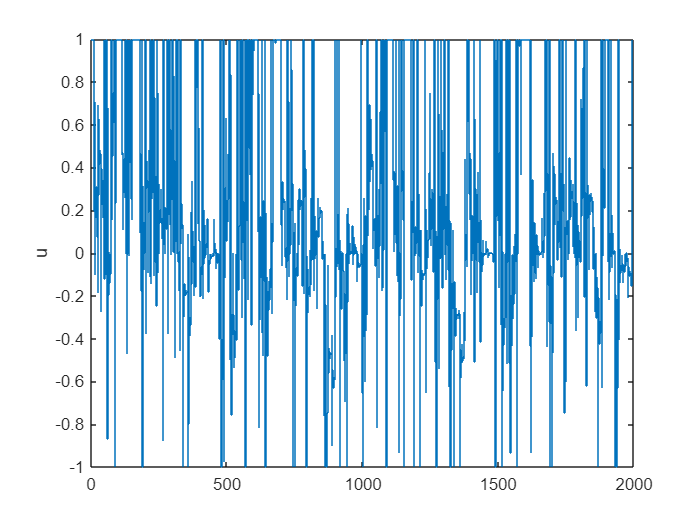


stairs(u)
ylabel('u')

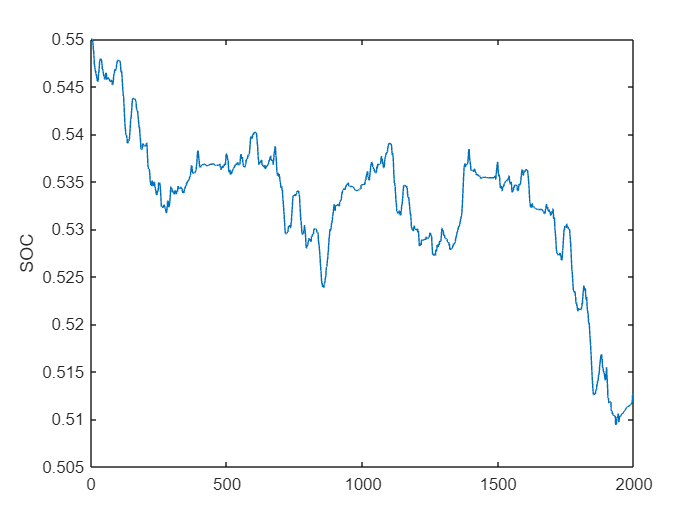

plot(SOC)
ylabel('SOC')

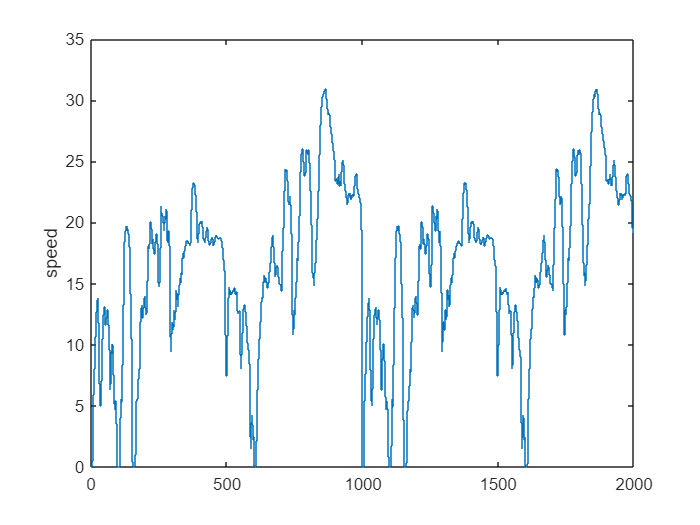

stairs(speed)
ylabel('speed')

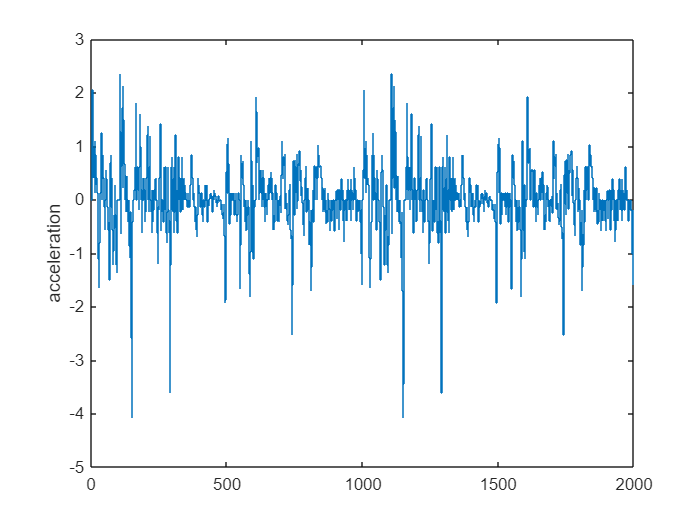

stairs(acceleration)
ylabel('acceleration')

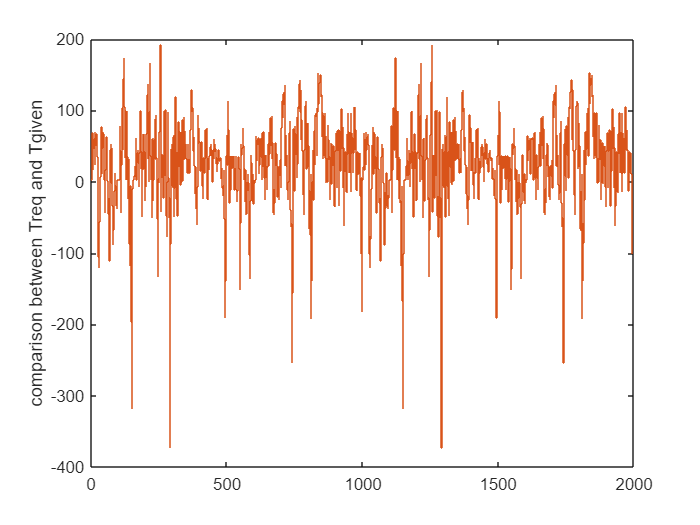

stairs(T_giv)
hold on
stairs(T_req)
hold off
ylabel('comparison between Treq and Tgiven')